## **System + data**

% Define system components
oqpskmod = comm.OQPSKModulator('BitInput', true);
oqpskdemod = comm.OQPSKDemodulator('BitOutput', true);
channel = comm.AWGNChannel('EbNo', 10, 'BitsPerSymbol', 2);
errorRate = comm.ErrorRate("ReceiveDelay", 4);

span = 4;                 % Filter span (number of symbols)
samplesPerSymbol = 8;      % Samples per symbol
rolloff = 0.5;               % Rolloff factor

txFilter = comm.RaisedCosineTransmitFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'OutputSamplesPerSymbol', samplesPerSymbol);

rxFilter = comm.RaisedCosineReceiveFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'InputSamplesPerSymbol', samplesPerSymbol, ...
    'DecimationFactor', samplesPerSymbol);


% Frame setup
numFrames = 12;             % Number of frames to transmit
frameSize = 2^8;        % Size of payload (in bits) per frame
preambleLength = 7;         % Barker code length
barkerGen = comm.BarkerCode("Length", preambleLength, 'SamplesPerFrame', preambleLength);
barkerCode = (barkerGen() + 1) / 2; % Map [-1, 1] to [0, 1]

% Generate multiple frames
txData = [];
for frameIdx = 1:numFrames
    % Generate payload for this frame
    payload = randi([0 1], frameSize, 1);

    % Create frame: [preamble | payload]
    frame = [barkerCode; payload];
    txData = [txData; frame]; %#ok<AGROW>
end

## Transmitter

% Modulate the signal
txSignal = oqpskmod(txData);

% Filter the signal at the transmitter (with upsampling)
txSignal = txFilter(txSignal);

## Receiver

% Pass the signal through the AWGN channel
rxSignal = channel(txSignal);

% Filter the signal at the Receiver (with downsampling)
rxSignal = rxFilter(rxSignal); 

### Symbol-Synchronize and Time Correction

rxData = oqpskdemod(rxSignal);
errorStats = errorRate(txData,rxData);
disp(["BER: ", errorStats(1)]);

    "BER: "    "0"



### Frame-Synchronize

# Time-Series

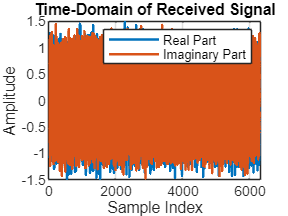

figure;
plot(real(rxSignal), 'LineWidth', 1.5,'DisplayName','Real Part');
hold on;
plot(imag(rxSignal), 'LineWidth', 1.5,'DisplayName','Imaginary Part');
title('Time-Domain of Received Signal');
xlabel('Sample Index');
ylabel('Amplitude');
legend();
grid on;
hold off;

# PSD

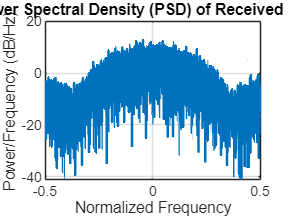

figure;
[psdValues, psdFreq] = periodogram(rxSignal, [], [], 1, 'centered');
plot(psdFreq, 10*log10(psdValues), 'LineWidth', 1.5);
title('Power Spectral Density (PSD) of Received Signal');
xlabel('Normalized Frequency');
ylabel('Power/Frequency (dB/Hz)');
grid on;

# Constellation

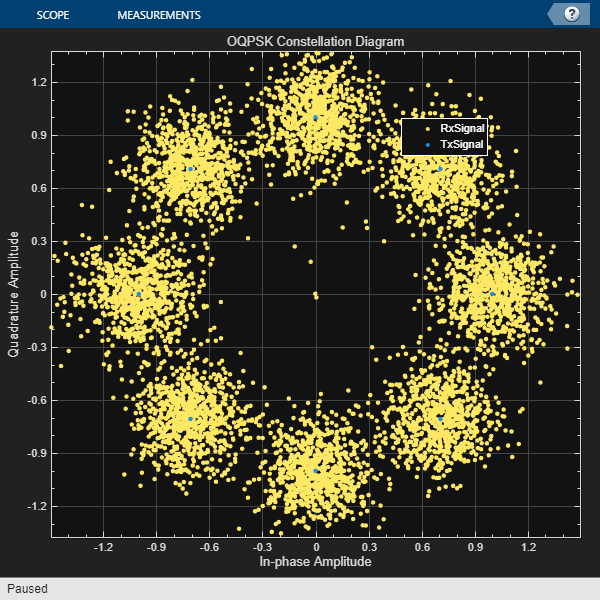

% Create a Constellation Diagram object
constDiagram = comm.ConstellationDiagram( ...
    'ReferenceConstellation', 0, ...
    'NumInputPorts', 2, ...
    'ShowLegend', true, ...
    'Title', 'OQPSK Constellation Diagram', ...
    'ChannelNames', {'RxSignal', 'TxSignal'});

% Visualize rxSignal and txSignal in the constellation diagram
constDiagram(rxSignal, oqpskmod(txData));

# Eye-Diagram

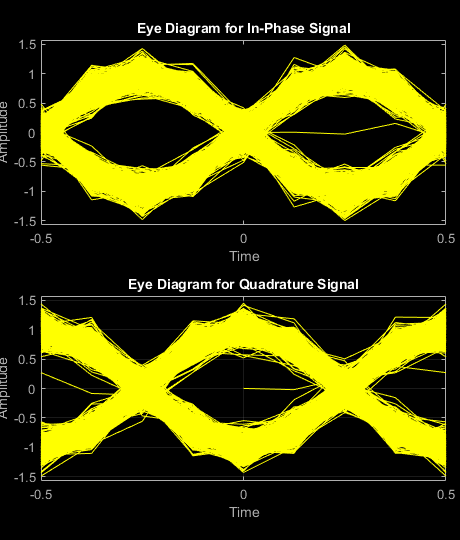

figure;
eyediagram(rxSignal, samplesPerSymbol);
xlabel('Time');
ylabel('Amplitude');
grid on;